## Loading the image

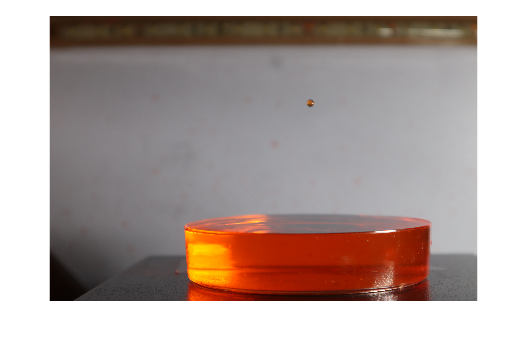

IMG_0016 = imread("High speed droplet imaging\2023_03_30\droplet in air\IMG_0016.JPG");
imshow(IMG_0016)

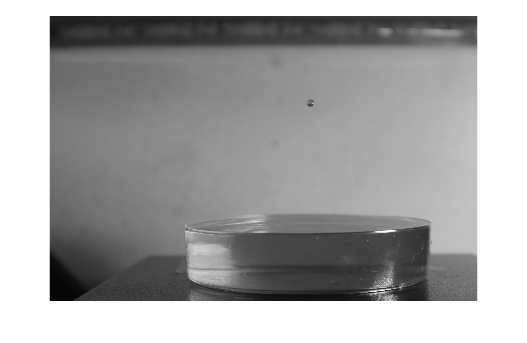


%converting the colored image to a grayscale image
image_gray=im2gray(IMG_0016);
imshow(image_gray)

## Preprocessing  

### Adjusting contrast

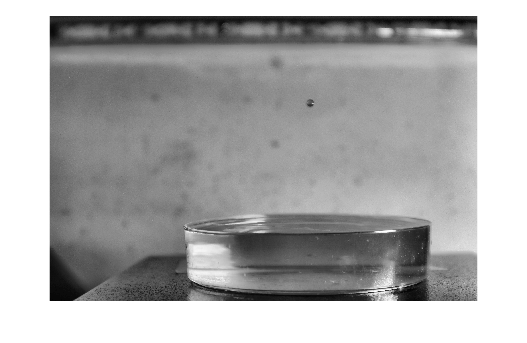

img2=adapthisteq(image_gray);
imshow(img2)

### Spatial filtering (smooth out the noise)

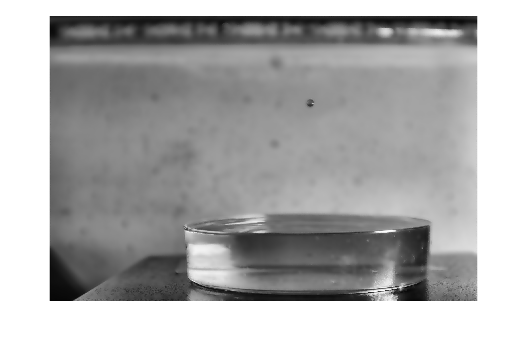

%we use a weiner filter (it's an adaptavie filter)
%play with the kernel size 
im_filtered = wiener2(img2,[50,50]);
imshow(im_filtered)

### After background subtraction

%se = strel('disk',10);
%im_no_background = imbothat(im_filtered,se);
%imshow(im_no_background)

## Segmenting based on color

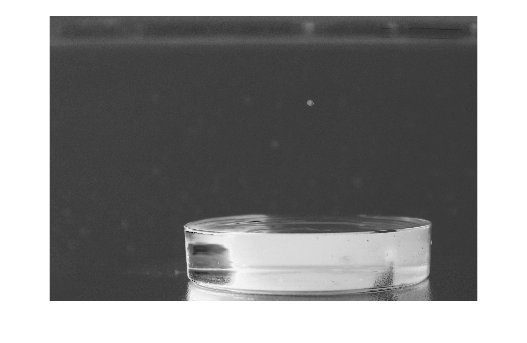

%play with these parameters a bit
imgLab = rgb2lab(IMG_0016);
[L,a,b] = imsplit(imgLab);
imshow(a,[])

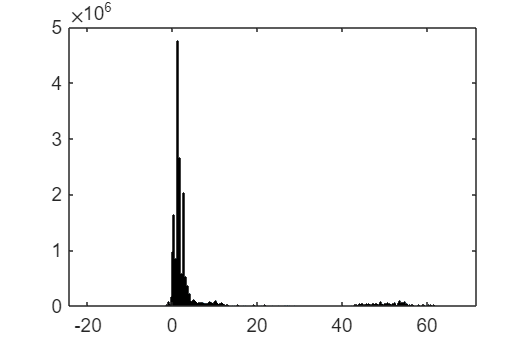


histogram(a)

orange_mask = a>10

orange_mask = 4000×6000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

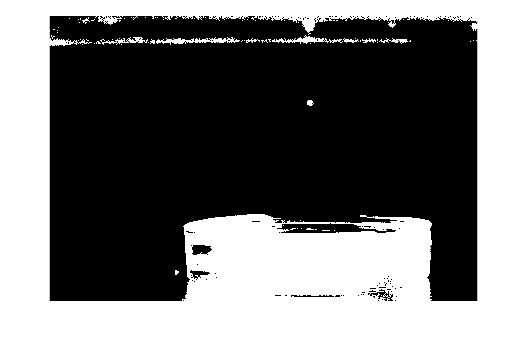

imshow(orange_mask)

## Segmenting based on texture

### Applying a texture filter

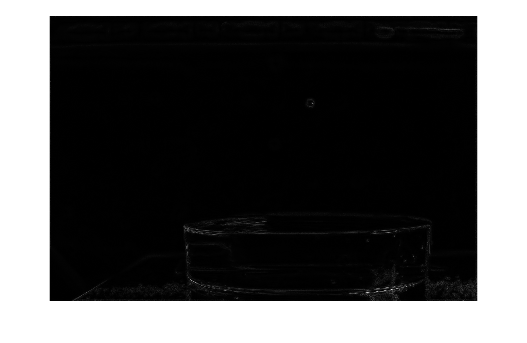

%play with the parameters
nHood = true(5);
tex_filt = rangefilt(im_filtered,nHood);
imshow(tex_filt)

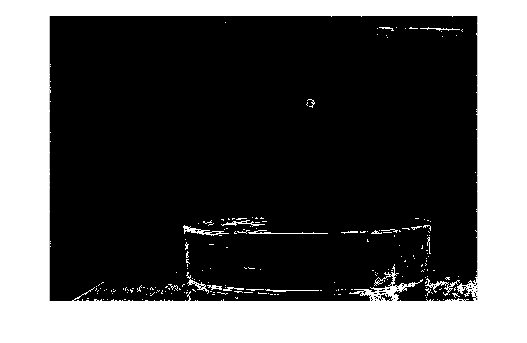


im_filtered2=imbinarize(tex_filt);
imshow(im_filtered2)

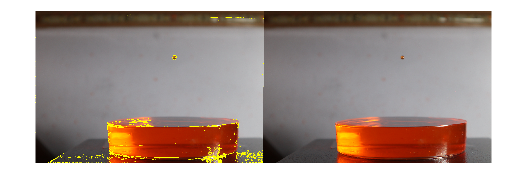


%viewing the overlay of the mask on the original image
%and comparing it with the mask obtained by color segmentation
overlay=imoverlay(IMG_0016,im_filtered2);
imshowpair(overlay,IMG_0016,"montage")

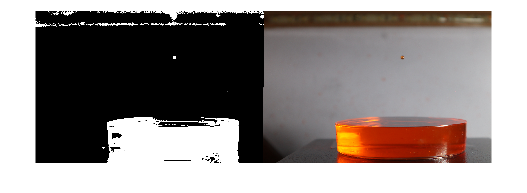

imshowpair(orange_mask,IMG_0016,"montage")

## Improving segmentations

### Applying a cleaning function to remove noise from binary mask

%play with the kernel size

%for im_filtered2 mask
se2 = strel("disk",25);
clean_mask2=imclose(im_filtered2,se2);
clean_mask2 = imfill(clean_mask2,"holes")

clean_mask2 = 4000×6000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

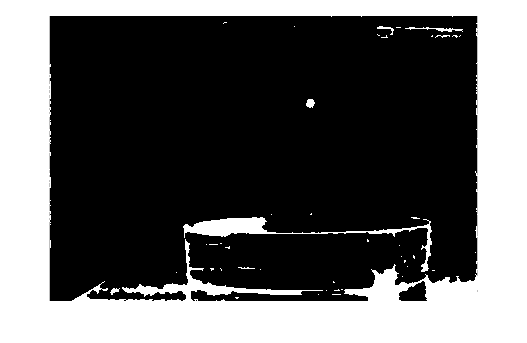

imshow(clean_mask2)


%for orange_mask mask
se3 = strel("disk",25);
clean_mask3=imclose(orange_mask,se3);
clean_mask3 = imfill(clean_mask3,"holes")

clean_mask3 = 4000×6000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

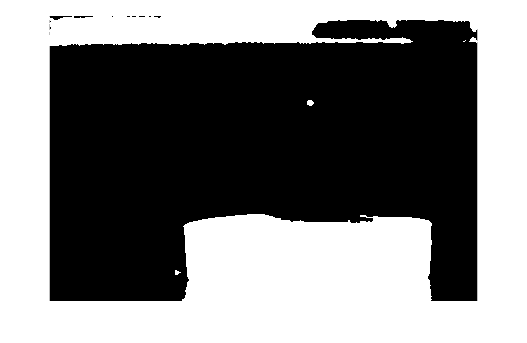

imshow(clean_mask3)


%right now clean_mask3 seems better (resembles the original better)

### Seperating the droplet from everything else

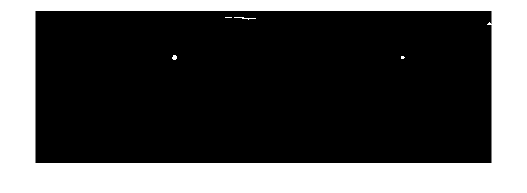

%find out a better way to do this

droplet1= bwpropfilt(clean_mask2,"Area",[10000 22500]);

droplet2= bwpropfilt(clean_mask3,"Area",[5000 10000]);

imshowpair(droplet1,droplet2,"montage")

## Detecting circles

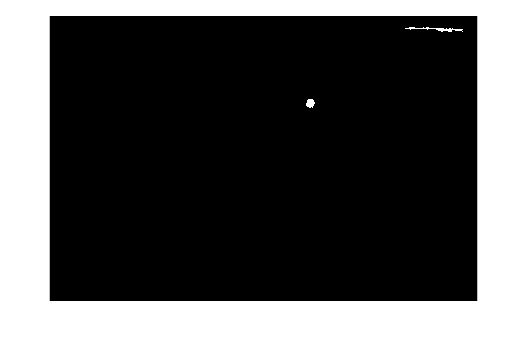

[c1,r1]=imfindcircles(droplet1,[50 200]);
[c2,r2]=imfindcircles(droplet2,[50 200]);

imshow(droplet1)
hold on
viscircles(c1, r1,'EdgeColor','b');
hold off

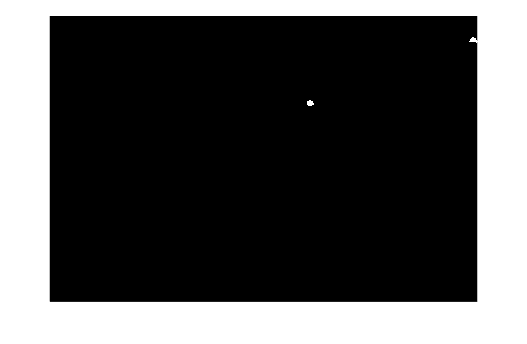


imshow(droplet2)
hold on
viscircles(c2, r2,'EdgeColor','b');
hold off